syms Ra V2 V0 V1 Cc s Cb Rd
A=[0 0 1 -1 -1 0 0;
0 0 0 0 1 -1 -1;
0 0 0 1 0 1 0;
1 0 0 Ra 0 0 0;
0 1 0 0 0 0 Rd;
0 -Cb*s 0 0 1 0 0;
-Cc*s Cc*s 0 0 0 1 0]

$$A = \left(\begin{array}{ccccccc} 0 & 0 & 1 & -1 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & -1 & -1\\ 0 & 0 & 0 & 1 & 0 & 1 & 0\\ 1 & 0 & 0 & \mathrm{Ra} & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0 & 0 & \mathrm{Rd}\\ 0 & -\mathrm{Cb}\,s & 0 & 0 & 1 & 0 & 0\\ -\mathrm{Cc}\,s & \mathrm{Cc}\,s & 0 & 0 & 0 & 1 & 0 \end{array}\right)$$

b=[0 0 0 V0 0 -Cb*s*V0 0]'

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ \bar{V_{0}}\\ 0\\ -\bar{\mathrm{Cb}}\,\bar{V_{0}}\,\bar{s}\\ 0 \end{array}\right)$$

x=A\b

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{\bar{V_{0}}+\mathrm{Cb}\,\mathrm{Rd}\,s\,\bar{V_{0}}+\mathrm{Cc}\,\mathrm{Rd}\,s\,\bar{V_{0}}-\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s\,\bar{\mathrm{Cb}}\,\bar{V_{0}}\,\bar{s}}{\sigma_{3}}\\ \frac{\mathrm{Rd}\,\sigma_{2}}{\sigma_{3}}\\ -\frac{\sigma_{2}}{\sigma_{3}}\\ -\sigma_{1}\\ -\frac{\bar{\mathrm{Cb}}\,\bar{V_{0}}\,\bar{s}-\sigma_{5}-\sigma_{6}+\sigma_{4}}{\sigma_{3}}\\ \sigma_{1}\\ -\frac{\sigma_{2}}{\sigma_{3}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\mathrm{Cc}\,s\,\bar{V_{0}}+\sigma_{5}-\sigma_{4}}{\sigma_{3}}\\ \sigma_{2}=\bar{\mathrm{Cb}}\,\bar{V_{0}}\,\bar{s}+\mathrm{Cc}\,s\,\bar{V_{0}}-\sigma_{6}\\ \sigma_{3}=\mathrm{Cb}\,\mathrm{Rd}\,s-\mathrm{Cc}\,\mathrm{Ra}\,s+\mathrm{Cc}\,\mathrm{Rd}\,s-\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s^{2}+1\\ \sigma_{4}=\mathrm{Cc}\,\mathrm{Rd}\,s\,\bar{\mathrm{Cb}}\,\bar{V_{0}}\,\bar{s}\\ \sigma_{5}=\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Rd}\,s^{2}\,\bar{V_{0}}\\ \sigma_{6}=\mathrm{Cc}\,\mathrm{Ra}\,s\,\bar{\mathrm{Cb}}\,\bar{V_{0}}\,\bar{s} \end{array}$$

x=A\b; Vo_LPF1=simplify(x(1))

$$Vo\_LPF1 = \frac{\bar{V_{0}}\,\left(\mathrm{Cb}+{\mathrm{Cb}}^{2}\,\mathrm{Rd}\,s+\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Rd}\,s-\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,{\left|\mathrm{Cb}\right|}^{2}\,{\left|s\right|}^{2}\right)}{\mathrm{Cb}\,\left(\mathrm{Cb}\,\mathrm{Rd}\,s-\mathrm{Cc}\,\mathrm{Ra}\,s+\mathrm{Cc}\,\mathrm{Rd}\,s-\mathrm{Cb}\,\mathrm{Cc}\,\mathrm{Ra}\,\mathrm{Rd}\,s^{2}+1\right)}$$

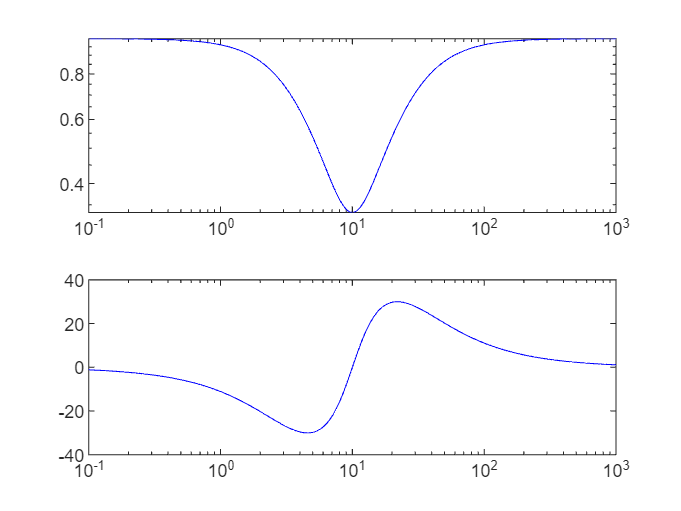

omega1=10; F_LPF1=RR_tf([1 omega1 omega1^2],[1 3*omega1 omega1^2]);
figure(1), RR_bode(F_LPF1)

syms Rb V2 V0 V1 Ca s Cd Rc
A=[0 0 1 -1 -1 0 0;
0 0 0 0 1 -1 -1;
0 0 0 1 0 1 0;
Ca*s 0 0 1 0 0 0;
0 -Cd*s 0 0 0 0 1;
0 1 0 0 Rb 0 0;
-1 1 0 0 0 -Rc 0]

$$A = \left(\begin{array}{ccccccc} 0 & 0 & 1 & -1 & -1 & 0 & 0\\ 0 & 0 & 0 & 0 & 1 & -1 & -1\\ 0 & 0 & 0 & 1 & 0 & 1 & 0\\ \mathrm{Ca}\,s & 0 & 0 & 1 & 0 & 0 & 0\\ 0 & -\mathrm{Cd}\,s & 0 & 0 & 0 & 0 & 1\\ 0 & 1 & 0 & 0 & \mathrm{Rb} & 0 & 0\\ -1 & 1 & 0 & 0 & 0 & -\mathrm{Rc} & 0 \end{array}\right)$$

b=[0 0 0 Ca*s*V0 0 V0 0]'

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ \bar{\mathrm{Ca}}\,\bar{V_{0}}\,\bar{s}\\ 0\\ \bar{V_{0}}\\ 0 \end{array}\right)$$

x=A\b

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{\bar{V_{0}}+\sigma_{4}+\mathrm{Rc}\,\bar{\mathrm{Ca}}\,\bar{V_{0}}\,\bar{s}+\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s\,\bar{\mathrm{Ca}}\,\bar{V_{0}}\,\bar{s}}{\sigma_{1}}\\ \frac{\bar{V_{0}}+\mathrm{Ca}\,\mathrm{Rc}\,s\,\bar{V_{0}}+\sigma_{4}}{\sigma_{1}}\\ \frac{\mathrm{Cd}\,s\,\bar{V_{0}}+\sigma_{3}+\sigma_{2}}{\sigma_{1}}\\ \frac{\sigma_{5}-\mathrm{Ca}\,s\,\bar{V_{0}}+\sigma_{2}}{\sigma_{1}}\\ \frac{\mathrm{Ca}\,s\,\bar{V_{0}}-\sigma_{5}+\mathrm{Cd}\,s\,\bar{V_{0}}+\sigma_{3}}{\sigma_{1}}\\ -\frac{\bar{V_{0}}\,\left(\bar{\mathrm{Ca}}\,\bar{s}-\mathrm{Ca}\,s+\mathrm{Cd}\,\mathrm{Rb}\,s\,\bar{\mathrm{Ca}}\,\bar{s}\right)}{\sigma_{1}}\\ \frac{\mathrm{Cd}\,s\,\bar{V_{0}}\,\left(\mathrm{Rb}\,\bar{\mathrm{Ca}}\,\bar{s}+\mathrm{Ca}\,\mathrm{Rc}\,s+1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{Ca}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Rc}\,s+\mathrm{Cd}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s^{2}+1\\ \sigma_{2}=\mathrm{Cd}\,\mathrm{Rb}\,s\,\bar{\mathrm{Ca}}\,\bar{V_{0}}\,\bar{s}\\ \sigma_{3}=\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rc}\,s^{2}\,\bar{V_{0}}\\ \sigma_{4}=\mathrm{Rb}\,\bar{\mathrm{Ca}}\,\bar{V_{0}}\,\bar{s}\\ \sigma_{5}=\bar{\mathrm{Ca}}\,\bar{V_{0}}\,\bar{s} \end{array}$$

x=A\b; Vo_LPF2=simplify(x(1))

$$Vo\_LPF2 = \frac{\bar{V_{0}}\,\left(\mathrm{Ca}\,s+\mathrm{Rb}\,{\left|\mathrm{Ca}\right|}^{2}\,{\left|s\right|}^{2}+\mathrm{Rc}\,{\left|\mathrm{Ca}\right|}^{2}\,{\left|s\right|}^{2}+\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s\,{\left|\mathrm{Ca}\right|}^{2}\,{\left|s\right|}^{2}\right)}{\mathrm{Ca}\,s\,\left(\mathrm{Ca}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Rc}\,s+\mathrm{Cd}\,\mathrm{Rb}\,s+\mathrm{Ca}\,\mathrm{Cd}\,\mathrm{Rb}\,\mathrm{Rc}\,s^{2}+1\right)}$$

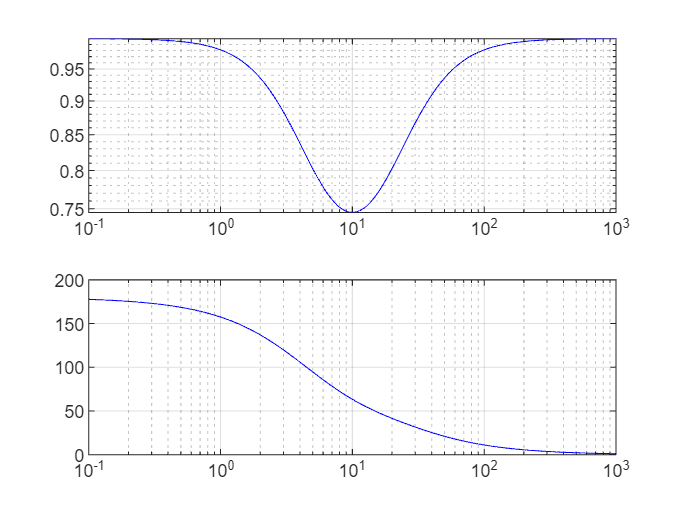

omega1=10; F_LPF2=RR_tf([1 omega1 -omega1^2],[1 3*omega1 omega1^2]);
%omega1=5; F_LPF3=RR_tf([1 omega1 -omega1^2],[1 3*omega1 omega1^2]);
%figure(22), RR_bode(F_LPF2)